% パラメータ
% a = 11.1674;
% b = 22.3668;
% L1 = 0.155;
% m2 = 0.1;
% l2 = 0.115;
% q_wn2 = 37.5762;
% g = 9.8;
% zeta = 0.0081 * sqrt(q_wn2);

% A = [0 0 1 0; 0 0 0 1; 0 0 -a 0; 0 q_wn2 q_wn2*(L1*a/g) 2*zeta]; 
% B = [0; 0; b; -q_wn2*(L1*b/g)];

% p = [-2 -2 -2 -2];

% K = acker(A, B, p);

% Qr = [100.0 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 0.1];
% Rr = [0.005];

% K2 = lqr(A, B, Qr, Rr)

エラー: acker (line 27)
A と B 行列は同じ行数でなければなりません。

seri = serialport("COM9", 57600, "ByteOrder", "big-endian", "Timeout", 0.1);

SAMPLING_TIME = 0.025;  % 1サンプルの頻度は25[ms]程度であることを予備実験で確認
INPUT_VOLTAGE = 0;
STEP_TIME = 2;

K2 = 	1.0e+03 *

   -0.1414   -2.1782   -0.0609   -0.3582


END_TIME = 5;

% % ゲイン？
% kp = 0.002;
% kd = 0.0001;

BASE = double(0x3FFFF);
%GOAL_ANGLE = 30/360 * BASE;
ARM = 1024;

% r=0*t+0.0;
% C = [1 0 0 0];
% lsim(A+B*K, B, C, r, t_sim)

% %パラメータ
% a = 10.1674;
% b = 112.8100;
L1 = 0.155;
m2 = 0.1;
l2 = 0.115;
% omega_n1 = 18.4101;
% omega_n2 = 6.0294;
% zeta1 = 0.2845;
% zeta2 = 0.0240;
% xi1 = 5.2374;
% xi2 = 0.1450;
% T = 1.0424;
% Tp = 0.1780;
% lambda = 0.8597;
% J2 = 0.0018;

ans = 	1.0e+03 *

   -1.6239
   -0.0096
   -0.0065
   -0.0057


% J2b = 0.0031;
% Kp = 3;
% g = 9.81; 

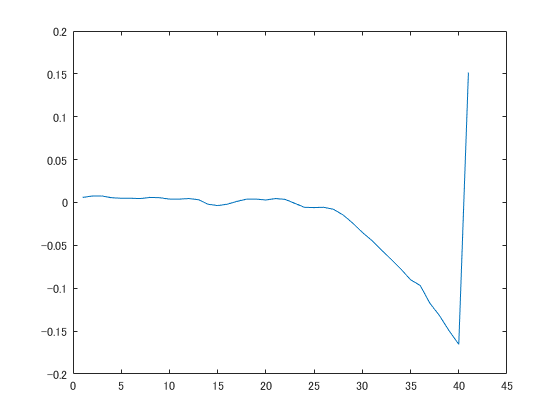

%取り敢えずゲインを求めてみる
A2 = [0 0 1 0; 0 0 0 1; 0 0 -a 0; 0 omega_n2^2 L1*a*omega_n2^2/g -2*xi2]; 

B2 = [0; 0; b; -L1*b*omega_n2^2/g];

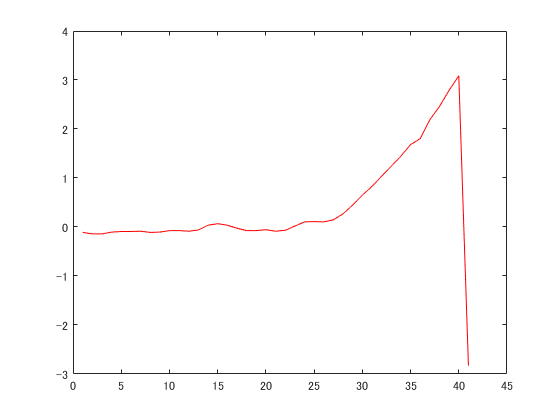

p = [-6.5; -6.5; -6.5; -6.5];

p2 = [-2; -2; -2; -2];

K3 = acker(A2, B2, p);

eig(A2-B2*K3)

Qr = [100.0 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 0.1];
Rr = [0.005];

K4 = lqr(A2, B2, Qr, Rr);

eig(A2-B2*K4)

% 初期値取得
for i = 1 : 100
    tic;
    
    write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    sh2pcTR0(i) = sci_read_with_decode_using_checksum(seri);    
    
    pause(SAMPLING_TIME - toc);
end
sh2pcTR0(100).ArmAngle
sh2pcTR0(100).TMStamp

% 目標値設定
arm_init = sh2pcTR0(100).ArmAngle;
arm_ref = arm_init + 512;

if arm_ref > 1024
    
    arm_ref = arm_ref - 1024;
    
end

%theta_ref = arm_ref*2*pi/ARM;
theta_ref = 0;

%% LQRかもしれない気がするようなこともあるかもしれない？

volt_t = double(0);
pause(10);
write(seri, typecast(swapbytes(volt_t), 'uint8'), 'uint8');

for j = 1 : 1000
    tic;
    disp(j);  
    
    sh2pcTR1(j) = sci_read_with_decode_using_checksum(seri);
    disp(sh2pcTR1(j).ArmAngle)
    
    arm_rad = armangle2rad(sh2pcTR1(j).ArmAngle, arm_init);
        
    arm_errs(j) = arm_rad - theta_ref;
    
    base_errs(j) = baseangle2rad(sh2pcTR1(j).BaseAngle); %[rad]
        
    if j == 1
        
        volt_t = double(K3(1)*base_errs(j) + K3(2)*arm_errs(j));
        %volt_t = double(K4(1)*base_errs(j) + K4(2)*arm_errs(j));
        
    else
        
        d_time(j) = double(sh2pcTR1(j).TMStamp - sh2pcTR1(j-1).TMStamp) / 1000; %時間差
        
        volt_t = double(K3(1)*base_errs(j) + K3(2)*arm_errs(j) + K3(3)*(base_errs(j)- base_errs(j-1))/d_time(j) + K3(4)*(arm_errs(j)- arm_errs(j-1))/d_time(j));
        %volt_t = double(K4(1)*base_errs(j) + K4(2)*arm_errs(j) + K4(3)*(base_errs(j)- base_errs(j-1))/d_time(j) + K4(4)*(arm_errs(j)- arm_errs(j-1))/d_time(j));
        
        d_arm_errs(j) = (arm_errs(j)- arm_errs(j-1))/d_time(j);
        d_base_errs(j) = (base_errs(j)- base_errs(j-1))/d_time(j);
        
    end
    
    volt_ts(j) = volt_t;
    
    if abs(volt_t) > 0.8
        
        volt_t = double(sign(volt_t)*0.8);
        
    end

    write(seri, typecast(swapbytes(volt_t), 'uint8'), 'uint8');
    
    disp(volt_t);
    disp(arm_errs(j)*180/pi);
    disp(base_errs(j)*180/pi);
    
    pause(SAMPLING_TIME - toc);
end

write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');

clear sh2pcTR0 sh2pcTR1 volt_t arm_errs arm_ref arm_init volt_ts d_time arm_rad base_errs theta_ref

% K3 = [-0.4346, -5.3601, -0.3636, -0.8679];
% K3_orig = K3;
K3 = K3_orig;

% plot(volt_ts(10:50));
% plot(base_errs(10:50)*180/pi);
% plot(K3(1)*base_errs(10:50));
% plot(arm_errs(10:50)*180/pi);
% figure(1);
 plot(K3(2)*arm_errs(10:50));
% figure(2);
 plot(arm_errs(10:50), 'r');
plot(diff(arm_errs(10:50)));

for l = 1:100

arm_rads(l) = armangle2rad(sh2pcTR1(l).ArmAngle, arm_init);

end

plot(arm_rads);